# Introduction

**Notes****:**

- `The ``%#ok`` statement at the end of a line removes the warning message about non used variable. I use it when I want to visualize a table, e.g. with t_filtered table, and I get the warning of non used variable.`

# Load data

clc; clear; close all;
addpath(genpath("astrodynamics\"));

data_file = uigetpath();
in = load(data_file);

# Convert it to tabular data

David de la Torre's original PCP data is in matrix format. The intended use of this data involves continuous revisiting, sorting, and filtering the data, much like a Excel table. As this will be the use of the data, it is preferable to have it stored in tabular form, instead of matrix form.

in

in = struct with fields:
    departure_planet: 'Mars'
      arrival_planet: 'Earth'
                cal0: {[2020]  [1]  [1]  [0]  [0]  [0]}
     departure_dates: [1×1000 double]
                tofs: [1×1000 double]
                  mr: 0
                  lp: 0
                opts: [1×1 struct]
              dbname: 'C:/workcopy_tfm_outputs/PCP/PCP_Mars2Earth_2020__P5_Y2_mr0_lp0/PCP_Mars2Earth.mat'
               jd2k0: 7.3045e+03
               fname: 'C:/workcopy_tfm_outputs/PCP/PCP_Mars2Earth_2020__P5_Y2_mr0_lp0/PCP_Mars2Earth'
                 c3d: [1000×1000 double]
                 c3a: [1000×1000 double]
                 dvd: [1000×1000 double]
                 dva: [1000×1000 double]
                 dvt: [1000×1000 double]
               theta: [1000×1000 double]


**I'm interested in variables; **departure_dates, tofs, c3d, c3a, dvd, dva, dvt, theta.

The rest of the variables will be added as **metadata** to the table.

in.dvd

ans =   437.6830  407.5004  381.1013  357.8139  337.1168  318.5990  301.9320  286.8505  273.1374  260.6136  249.1301  238.5617  228.8026  219.7627  211.3647  203.5423  196.2378  189.4010  182.9881  176.9605  171.2843  165.9293  160.8687  156.0787  151.5380  147.2274  143.1297  139.2293  135.5122  131.9656  128.5779  125.3385  122.2378  119.2670  116.4180  113.6833  111.0562  108.5302  106.0997  103.7593  101.5039   99.3289   97.2301   95.2036   93.2454   91.3524   89.5211   87.7486   86.0321   84.3689
  436.8766  406.7431  380.3867  357.1369  336.4730  317.9847  301.3443  286.2866  272.5952  260.0911  248.6256  238.0737  228.3297  219.3038  210.9189  203.1085  195.8152  188.9889  182.5858  176.5674  170.8998  165.5529  160.5000  155.7173  151.1835  146.8794  142.7879  138.8934  135.1819  131.6407  128.2581  125.0237  121.9278  118.9615  116.1168  113.3864  110.7633  108.2413  105.8146  103.4778  101.2259   99.0544   96.9590   94.9357   92.9808   91.0908   89.2625   87.4930   85.7794   

- Rows **vs** Colums = Departure dates **vs** time of flight (tof).

## Create the table

cols = ["DepDates","tof","c3d","c3a","dvd","dva","dvt","theta"];
N = length(in.tofs); %A N by N matrix has N^2 elements

t = table(nan(N^2,1) , ...
          nan(N^2,1) , ...
          nan(N^2,1) , ...
          nan(N^2,1) , ...
          nan(N^2,1) , ...
          nan(N^2,1) , ...
          nan(N^2,1) , ...
          nan(N^2,1) , 'VariableNames', cols) %trasposed vectors .

## Fill the table

tic; k = 1;
      for i = 1:N %DepDates

t = 1000000×8 table
    DepDates    tof    c3d    c3a    dvd    dva    dvt    theta
    ________    ___    ___    ___    ___    ___    ___    _____

      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
      NaN       NaN    NaN    NaN    NaN    NaN    NaN     NaN 
   

          for j = 1:N %tof
              
              % Variables independientes
              t.DepDates(k) = in.departure_dates(i); %DepDates
              t.tof(k) = in.tofs(j); %tof
              
              % Variables dependientes
              t.c3d(k) = in.c3d(i,j); %c3d
              t.c3a(k) = in.c3a(i,j); %c3a
              t.dvd(k) = in.dvd(i,j); %dvd
              t.dva(k) = in.dva(i,j); %dva
              t.dvt(k) = in.dvt(i,j); %dvt
              t.theta(k) = in.theta(i,j); %theta
              
              k = k+1;
          end
          disp(i)
      end
toc
% It took 17s for a 10k elements table, on my old HP EliteBook 2560p
% Will take 6.5h for a 1M elements table, on my old Macbook Air 13 (early
% 2015)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



Elapsed time is 30141.825621 seconds.


## Adding metadata to the table

% Pending to code

writetable(t);

# Applying conditions to the table

Once the table is built, we can apply conditions to it, to filter the data as desired. For example:

- Find the trajectories departing from Earth starting on 20th July 2020.

- Find the trajectories departing from Earth starting on 20th July 2020 & arriving to Mars before 1st May 2024.

- Find the trajectories with dvt<=10.5 km/s.

- Find the trajectories with dvt<=10.5 & c3d<=36 & type I

- Launch window

- Find the next launch window starting from 20th July 2026.

- Find the previous launch window to 20th July 2026.

- Any logical combination of any of the above conditions.

## **1. Filtering by departure dates**

% % Find the trajectories departing from Earth starting on 20th July 2020.
c1 = Cal2JD ( 2020, 7, 20, 12, 0, 0, 'J2000' ); %c1 stands for condition 1.
rows = t.DepDates > c1;

t_filtered = t(rows,:) %#ok

## **2. Filtering by departure dates and time of flight**

% Find the trajectories departing from Earth starting on 20th July 2020 & arriving to Mars before 1st May 2024.
d1 = Cal2JD ( 2020, 7, 20, 12, 0, 0, 'J2000' ); % d1, d2, ... d stands for date
d2 = Cal2JD ( 2024, 5, 1, 12, 0, 0, 'J2000' );

rows = (t.DepDates > d1) & (t.DepDates + t.tof < d2);

t_filtered = t(rows,:)
unique(t_filtered.DepDates > d1) % Checking conditions applied
unique(t_filtered.DepDates + t_filtered.tof < d2) % Checking conditions applied

## **3. Filtering by trajectory energy**

% Find the trajectories with dvt<=10.5 km/s.
c1 = 10.5;

rows = (t.dvt <= c1);

t_filtered = t(rows,:) %#ok

## **4. Filtering by trajectory energy II**

% Find the trajectories with dvt<=10.5 & c3d<=36 & type I
c1 = 10.5;
c2 = 36.0;
c3 = deg2rad(180.0);

rows = (t.dvt <= c1) & (t.c3d <= c2) & (t.theta < c3);

t_filtered = t(rows,:) %#ok

## **5. Launch window**

- **Initial mode**l: the blue areas aka all those trajectories with time of flight $tof_{min} \leq tof \leq tof_{max} $ AND ( $\Delta v_t \leq \Delta v_t^{  max}$ OR $C3_d$ OR $C3_a

$ )

-     The actual values of $tof_{min} \ ,\ tof_{max} \ ,\ \Delta v_t^{max}\ ,\ C3_d^{max} \ ,\ C3_a^{max}$,  will be taken from available launcher architectures information or best estimates.

-     Once we have more information regarding launching capabilities from Earth (e.g. one launch every 30d, launch azimuth limitations, etc) we could add complexity to the conditions if needed.

                   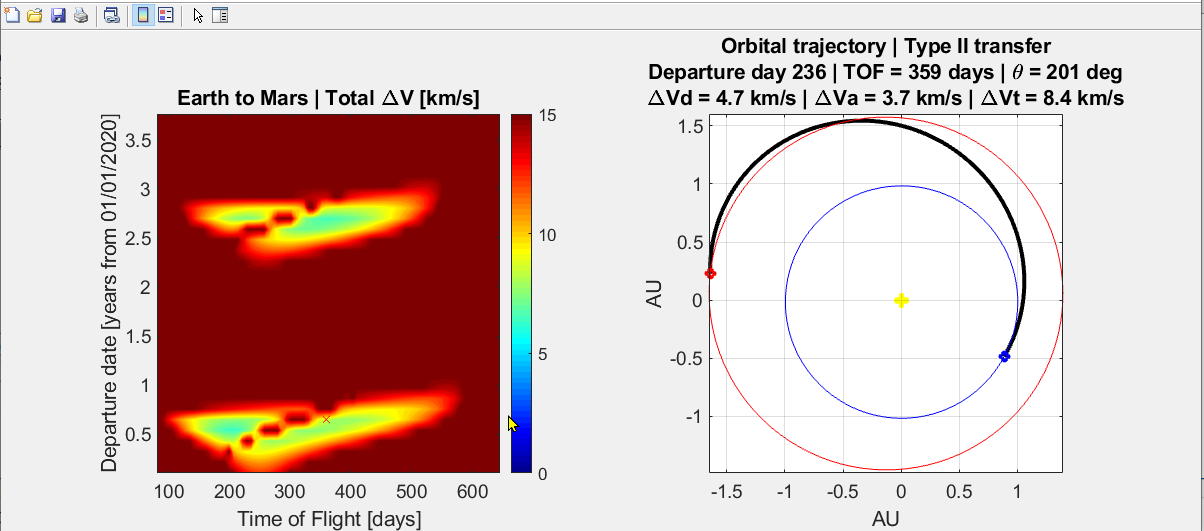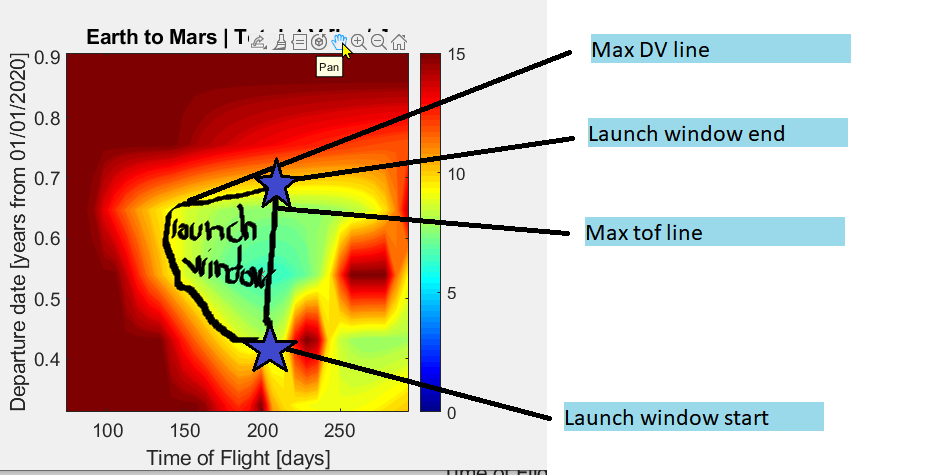

- Trajectories type:

-     I: theta < 180

-     II: 180 < theta < 360

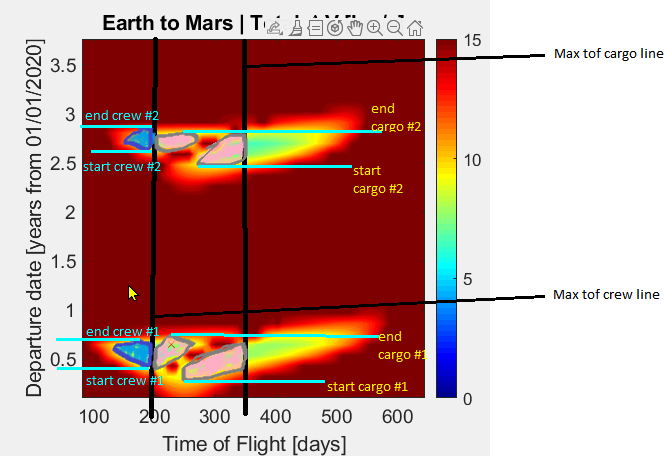

% Apply conditions to filter all the blue/yellow/green areas, which are
% potential launch windows for cargo/crewed missions.

% When identifying all the launch windows, we are not interested in
% filtering by date, so we consider all the available departure dates in
% the dataset.

% The conditions.
tof_min = 0; %days
tof_max = 200;
dvt_max = 14; %km/s
c3d_max = 80; %km2/s2
c3a_max = 36;
theta_min = 0; %rad
theta_max = deg2rad(360.0);

% summary(t)
rows = (t.tof > tof_min & t.tof < tof_max) & ...
        (t.dvt < dvt_max) & ...
         (t.c3d < c3d_max) & ...
          (t.c3a < c3a_max) & ...
            (t.theta > theta_min & t.theta < theta_max);
% occurrences(rows)
t_filtered = t(rows,:);
% sortrows(t_filtered,["tof","c3d"],"descend")
% sortrows(t_filtered,"tof","descend")

To identify each launch opportunity, I will sort the DepDates field in ascending order. Then, I will assign opportunity number 1 to all the rows till I find a row which DepDate is 100 days more than the previous. 

This will work because I know that the Synodic period between Earth-Mars is aboun 680 days, so I know for sure that with the last departure date of a launch opportunity will be at least 100 days separated from the first departure date from the next lauch opportunity.

sortrows(t_filtered,"DepDates","ascend")
N = length(t_filtered.DepDates);
t_filtered.loppt = nan(N,1); % loppt stands for launch opportunity :).
t_filtered
NLOppt = 1; %NLOppt is the launch opportunity counter.
LOpptSep = 100; %As a 1st approach, the separation between launch opportunities ...
% will be assumed of at least 100 days, as we know that the synodic period
% is about 700 days.
i = 1;
DepDates2020 = Cal2JD ( 2020, 1, 1, 12, 0, 0, 'J2000' );
t_filtered.DepDates = t_filtered.DepDates - DepDates2020;
while i ~= N
    
    
    t_filtered.loppt(i) = NLOppt;
    
    DepDatesDiff = t_filtered.DepDates(i+1) - t_filtered.DepDates(i);
    if (DepDatesDiff >= LOpptSep) , NLOppt = NLOppt+1; end
    
    i = i+1;
end

% i == N
t_filtered.loppt(i) = NLOppt;

t_filtered